Define_Constants

# Independent GNSS solution

## Epoch 0

Getting a position solution for epoch 0 and checking for outliers

x_cap_old= zeros(3, 1);
v_cap_e_ea_old= zeros(3, 1);


prange_datafile = readmatrix("CW1/Pseudo_ranges.csv");
sat_index= prange_datafile(1, 2:end);
sat_count= numel(sat_index);
idx= 2; % row 2 corresponds to epoch 0
sim_time= prange_datafile(idx, 1);


est_r_e_esati= zeros(sat_count, 3);
est_v_e_esati= zeros(sat_count, 3);

for index = 1: sat_count
    [est_r_e_esati(index, :) , est_v_e_esati(index, :)]= ...
        Satellite_position_and_velocity(sim_time, sat_index(index));
end

obs_prange_a_sati = prange_datafile(idx, 2:end)';


[pos_soln]= Single_Epoch_position(sim_time, ...
    x_cap_old, v_cap_e_ea_old, sat_index, obs_prange_a_sati);


pred_clock_offset= pos_soln(4, 1);


pred_prange_asati= zeros(sat_count, 1);

u_e_asati= zeros(sat_count, 3);


for index = 1: numel(sat_index)

    [pred_prange_asati(index, 1), u_e_asati(index, :)]= ...
        line_of_sight_vector(est_r_e_esati(index, :)', pos_soln(1:3, 1));

end

meas_mat= horzcat(-u_e_asati, ones( sat_count, 1));

A= inv(meas_mat' * meas_mat);
B= meas_mat*A*meas_mat';
C= B- eye(sat_count);

pred_meas_innov= obs_prange_a_sati- pred_prange_asati - pred_clock_offset;

residuals= C* pred_meas_innov;

C= eye(sat_count)- B;
residuals_cov= C* 5^2;



for i2=1:sat_count
    LHS= abs(residuals(i2));
    RHS= sqrt(residuals_cov(i2, i2))*6;
    outlier= LHS> RHS;

    fprintf("sat %d |V_%d|= %0.2f >  sqrt(C_%d%d)*T= %0.2f ----> %d\n", ...
        sat_index(i2),i2, LHS, ...
        i2, i2, RHS, ...
        outlier)
end

sat 5 |V_1|= 2.69 >  sqrt(C_11)*T= 24.27 ----> 0
sat 6 |V_2|= 4.62 >  sqrt(C_22)*T= 23.15 ----> 0
sat 7 |V_3|= 4.81 >  sqrt(C_33)*T= 17.98 ----> 0
sat 9 |V_4|= 4.31 >  sqrt(C_44)*T= 15.43 ----> 0
sat 10 |V_5|= 2.79 >  sqrt(C_55)*T= 22.63 ----> 0
sat 11 |V_6|= 1.85 >  sqrt(C_66)*T= 23.49 ----> 0
sat 15 |V_7|= 2.24 >  sqrt(C_77)*T= 24.25 ----> 0
sat 30 |V_8|= 1.74 >  sqrt(C_88)*T= 16.19 ----> 0


fprintf("%0.5f %0.5f %0.5f %0.5f", pos_soln)

3977851.13166 -11180.86981 4969033.74260 10008.80095






[DR_lat_rad, DR_long_rad, height_m]= pv_ECEF_to_NED(pos_soln(1:3), [0 0 0]');

DR_lat_deg= rad_to_deg*DR_lat_rad;

DR_long_deg= rad_to_deg* DR_long_rad;

fprintf("%.6f %.6f %.2f\n", DR_lat_deg, DR_long_deg, height_m)

51.509254 -0.161045 38.83


Velocity solution for epoch 0


x_cap_old= zeros(3, 1);
v_cap_e_ea_old= zeros(3, 1);

prange_datafile= readmatrix("CW1/Pseudo_ranges.csv");
prange_rate_data= readmatrix("CW1/Pseudo_range_rates.csv");


sat_index= prange_datafile(1, 2:end);
sat_count= numel(sat_index);
idx= 2; % what row to consider DO NOT TAKE 1
sim_time= prange_datafile(idx, 1);


est_r_e_esati= zeros(sat_count, 3);
est_v_e_esati= zeros(sat_count, 3);

for index = 1: sat_count
    [est_r_e_esati(index, :) , est_v_e_esati(index, :)]= ...
        Satellite_position_and_velocity(sim_time, sat_index(index));
end

obs_prange_a_sati = prange_datafile(idx, 2:end)';
obs_prange_rate_asati= prange_rate_data(idx, 2:end)';




[pos_soln]= Single_Epoch_position(sim_time, ...
    x_cap_old, v_cap_e_ea_old, sat_index, obs_prange_a_sati);


pred_r_ea= pos_soln(1:3, 1);


[vel_soln] = Single_epoch_velocity(sim_time, pred_r_ea, ...
    sat_index, obs_prange_rate_asati);


est_v_ea= vel_soln(1:3, 1);


% resolving in lat, long, h, v_N, v_E, v_D
[DR_lat_rad, DR_long_rad, height_m, est_v_ea_resolved]= pv_ECEF_to_NED(pred_r_ea, est_v_ea);

DR_lat_deg= rad_to_deg*DR_lat_rad

DR_lat_deg =   51.509254461295079



DR_long_deg= rad_to_deg* DR_long_rad

DR_long_deg =   -0.161045484926372


height_m

height_m =   38.825816915370524



fprintf("Lat : %.6f Long : %.6f H : %.2f\n", DR_lat_deg, DR_long_deg, height_m)

Lat : 51.509254 Long : -0.161045 H : 38.83


fprintf("N : %.2f m/s E : %.2f m/s D : %.2f m/s\n", est_v_ea_resolved)

N : -0.02 m/s E : 0.05 m/s D : 0.01 m/s


## KALMAN

## Epoch 1 and later

We use the values from Epoch 0 to initialise the Kalman Filter

prange_datafile= readmatrix("Pseudo_ranges.csv");
prange_rate_data= readmatrix("Pseudo_range_rates.csv");


epochs= prange_datafile(2:end, 1);
sat_index= prange_datafile(1, 2:end);
sat_count= numel(sat_index);

Writing solution in a file

GNSS_pos_vel= zeros(size(prange_datafile, 1)-1, 7);
% row 1 is satellite ids

for idx= 2:size(prange_datafile, 1)

    sim_time= prange_datafile(idx, 1);
    prop_time= 0.5; % make this dynamic


    % meas_range_asati= meas_range_data(idx, 2:end);
    obs_prange_a_sati = prange_datafile(idx, 2:end)';

    % meas_range_rate_asati= meas_range_rate_data(idx, 2:end);
    obs_prange_rate_asati= prange_rate_data(idx, 2:end)';
    
    
    if sim_time ==0
        % Initialise Kalman filter state estimates that will be used ONLY for first iteration
        
        [est_state_last,est_error_cov_mat_last]= Initialise_GNSS_KF_CW();

        [est_state_new, est_error_cov_mat_new]= ...
        GNSS_Kalman_filter(est_state_last, est_error_cov_mat_last,...
        sat_index, sat_count, sim_time, prop_time, ...
        obs_prange_a_sati, obs_prange_rate_asati);

    else
        [est_state_new, est_error_cov_mat_new]= ...
        GNSS_Kalman_filter(est_state_last, est_error_cov_mat_last,...
        sat_index, sat_count, sim_time, prop_time, ...
        obs_prange_a_sati, obs_prange_rate_asati);
    end

    [DR_lat_rad, DR_long_rad, height_m, est_v_ea_resolved]= ...
        pv_ECEF_to_NED(est_state_new(1:3, 1), est_state_new(4:6, 1));
    
    DR_lat_deg= rad_to_deg*DR_lat_rad;
    
    DR_long_deg= rad_to_deg* DR_long_rad;

    if idx < 20
        fprintf("Epoch : %d", sim_time)
        fprintf("Lat : %.6f Long : %.6f H : %.2f\n", DR_lat_deg, DR_long_deg, height_m)
        fprintf("N : %.2f m/s E : %.2f m/s D : %.2f m/s\n\n", est_v_ea_resolved)
    end


    est_state_last = est_state_new;
    est_error_cov_mat_last= est_error_cov_mat_new;
    
    GNSS_pos_vel(idx-1, 1)= sim_time;
    GNSS_pos_vel(idx-1, 2)= DR_lat_deg;
    GNSS_pos_vel(idx-1, 3)= DR_long_deg;
    GNSS_pos_vel(idx-1, 4)= height_m;
    GNSS_pos_vel(idx-1, 5)= est_v_ea_resolved(1, 1);
    GNSS_pos_vel(idx-1, 6)= est_v_ea_resolved(2, 1);
    GNSS_pos_vel(idx-1, 7)= est_v_ea_resolved(3, 1);


    % if time_index ==4
    % 
    % break
    % end
    % break
end

Epoch : 0

Lat : 51.509254 Long : -0.161045 H : 38.82


N : -0.02 m/s E : 0.05 m/s D : 0.01 m/s



Epoch : 5.000000e-01

Lat : 51.509246 Long : -0.161042 H : 38.46


N : 0.15 m/s E : -0.02 m/s D : -0.02 m/s



Epoch : 1

Lat : 51.509247 Long : -0.161047 H : 37.50


N : 0.24 m/s E : 0.01 m/s D : 0.01 m/s



Epoch : 1.500000e+00

Lat : 51.509253 Long : -0.161044 H : 37.41


N : 0.51 m/s E : -0.02 m/s D : 0.03 m/s



Epoch : 2

Lat : 51.509255 Long : -0.161044 H : 37.00


N : 0.76 m/s E : 0.01 m/s D : 0.05 m/s



Epoch : 2.500000e+00

Lat : 51.509259 Long : -0.161046 H : 37.02


N : 0.98 m/s E : 0.01 m/s D : -0.02 m/s



Epoch : 3

Lat : 51.509262 Long : -0.161041 H : 37.13


N : 1.24 m/s E : 0.01 m/s D : -0.03 m/s



Epoch : 3.500000e+00

Lat : 51.509267 Long : -0.161039 H : 37.12


N : 1.24 m/s E : -0.02 m/s D : -0.01 m/s



Epoch : 4

Lat : 51.509275 Long : -0.161038 H : 36.74


N : 1.24 m/s E : -0.01 m/s D : -0.06 m/s



Epoch : 4.500000e+00

Lat : 51.509279 Long : -0.161036 H : 36.03


N : 1.25 m/s E : -0.00 m/s D : -0.03 m/s



Epoch : 5

Lat : 51.509285 Long : -0.161038 H : 36.07


N : 1.24 m/s E : 0.00 m/s D : -0.09 m/s



Epoch : 5.500000e+00

Lat : 51.509292 Long : -0.161038 H : 35.80


N : 1.26 m/s E : -0.03 m/s D : -0.06 m/s



Epoch : 6

Lat : 51.509295 Long : -0.161038 H : 35.51


N : 1.23 m/s E : 0.04 m/s D : -0.06 m/s



Epoch : 6.500000e+00

Lat : 51.509301 Long : -0.161036 H : 35.54


N : 1.24 m/s E : 0.02 m/s D : -0.03 m/s



Epoch : 7

Lat : 51.509308 Long : -0.161035 H : 35.73


N : 1.27 m/s E : -0.01 m/s D : -0.01 m/s



Epoch : 7.500000e+00

Lat : 51.509313 Long : -0.161034 H : 36.06


N : 1.25 m/s E : 0.01 m/s D : -0.04 m/s



Epoch : 8

Lat : 51.509319 Long : -0.161032 H : 35.95


N : 1.24 m/s E : 0.00 m/s D : -0.01 m/s



Epoch : 8.500000e+00

Lat : 51.509325 Long : -0.161032 H : 36.06


N : 1.26 m/s E : -0.00 m/s D : -0.05 m/s



filename = 'CW1/CW_GNSS_pos_vel.csv';
% epoch,  lat_deg,  long_deg,  height_m,  v_N,  v_E,  v_D

% Write the matrix to a CSV file
writematrix(GNSS_pos_vel, filename);

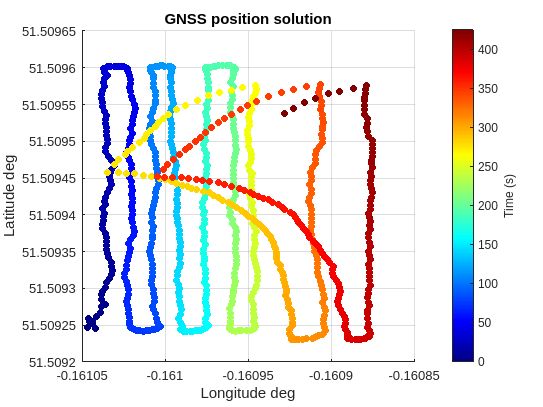

% position plot with time as cmap
p= scatter(GNSS_pos_vel(:, 3), GNSS_pos_vel(:, 2), 30, epochs, 'filled');  % 'o' specifies the marker style (you can use other markers as well)
colormap(jet);  % Choose colormap (you can change to other colormaps if desired)

% Add colorbar with title
c = colorbar;
xlabel(c, 'Time (s)');  % Label for colorbar

xlabel('Longitude deg');  % Label for x-axis
ylabel('Latitude deg');  % Label for y-axis

title("GNSS position solution")
grid on;

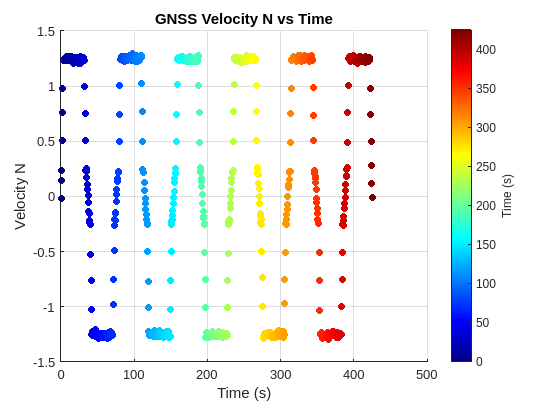

% velocity N E plot vs time time is also the cmap just to be consistent

% position plot with time as cmap
p= scatter(epochs, GNSS_pos_vel(:, 5), 30, epochs, 'filled');  % 'o' specifies the marker style (you can use other markers as well)
colormap(jet);  % Choose colormap (you can change to other colormaps if desired)

% Add colorbar with title
c = colorbar;
xlabel(c, 'Time (s)');  % Label for colorbar

xlabel('Time (s)');  % Label for x-axis
ylabel('Velocity N');  % Label for y-axis

title("GNSS Velocity N vs Time")
grid on;

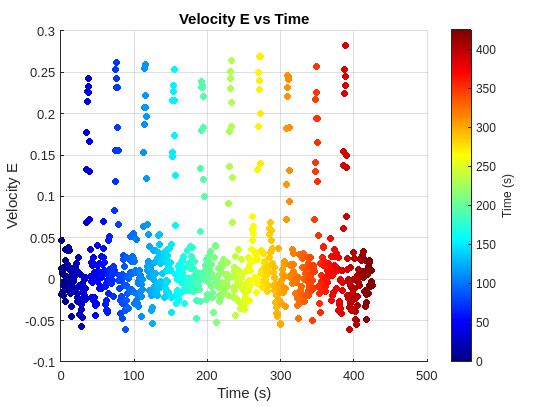

% velocity N E plot vs time time is also the cmap just to be consistent

% position plot with time as cmap
p= scatter(epochs, GNSS_pos_vel(:, 6), 30, epochs, 'filled');  % 'o' specifies the marker style (you can use other markers as well)
colormap(jet);  % Choose colormap (you can change to other colormaps if desired)

% Add colorbar with title
c = colorbar;
xlabel(c, 'Time (s)');  % Label for colorbar

xlabel('Time (s)');  % Label for x-axis
ylabel('Velocity E');  % Label for y-axis

title("Velocity E vs Time")
grid on;

# DR solution

GNSS_pos_vel= readmatrix("CW1/CW_GNSS_pos_vel.csv");
speed_heading_data= readmatrix("CW1/Dead_reckoning.csv");

For Speed : we are averaging the measuements from 4 wheels

Heading : as is

epochs= speed_heading_data(:, 1);


% For
speed_data= mean(speed_heading_data(:,2:5), 2); 

% heading_data_deg= speed_heading_data(:, 7);
% heading_data_deg= correctHeadingWithGyroscope(speed_heading_data);
heading_data_deg= correctHeadingWithGyroscopeKalman(speed_heading_data);

% this is in degrees so we convert it to radians

heading_data_rad= heading_data_deg* deg_to_rad;

Initial latitude and longitude We take epoch 0 value from GNSS solution

DR_lat_deg= zeros(size(speed_data));
DR_lat_deg(1) = GNSS_pos_vel(1, 2); 
DR_lat_rad= DR_lat_deg* deg_to_rad;

DR_long_deg = zeros(size(speed_data));
DR_long_deg(1)= GNSS_pos_vel(1, 3);
DR_long_rad= DR_long_deg* deg_to_rad;

DR_speed_N= zeros(size(speed_data));
DR_speed_E= zeros(size(speed_data));

For the very first epoch at time=0 we do not have previous epoch heading values.

So we take only the current epoch heading reading into consideration


$$v_{N, 0}= v_0\cos\Psi_0$$



$$v_{E, 0}= v_0\sin\Psi_0$$


DR_speed_N(1)= cos(heading_data_rad(1))* speed_data(1);
DR_speed_N(1)

ans =      0


DR_speed_E(1)= sin(heading_data_rad(1))* speed_data(1);
DR_speed_E(1)

ans =      0


Calculating average velocity at all epochs **without damping**

DR_speed_N(2:end)= (0.5 * (cos(heading_data_rad(2:end))+ cos(heading_data_rad(1:end-1)))) .* speed_data(2:end)

DR_speed_N =                    0
   0.019974731503757
   0.139847502200928
   0.324984671760103
   0.544967205004760
   0.749979205274813
   1.009983118342037
   1.154894692866349
   1.288998313814794
   1.264026614445404


DR_speed_E(2:end)= 0.5 * (sin(heading_data_rad(2:end))+ sin(heading_data_rad(1:end-1))) .* speed_data(2:end)

DR_speed_E =                    0
  -0.000926817562126
  -0.004229362436748
   0.002923802737935
   0.001003376354843
  -0.001298167562045
   0.005833486994528
   0.013950009120873
  -0.022297795279259
  -0.044281069251082


Latitude Longitude calculation

height is taken as the  height etimated by GNSS



for i=2:size(DR_speed_N, 1)
    h= GNSS_pos_vel(i-1, 4);
   
    [R_N, R_E]= Radii_of_curvature(DR_lat_rad(i-1));

    DR_lat_rad(i)= DR_lat_rad(i-1) + ((DR_speed_N(i)*(epochs(i)- epochs(i-1)))/(R_N+ h));
    DR_lat_deg(i)= DR_lat_rad(i)*  rad_to_deg;

    DR_long_rad(i)= DR_long_rad(i-1) + ((DR_speed_E(i)*(epochs(i)- epochs(i-1)))/((R_E+ h)* cos(DR_lat_rad(i) )));
    DR_long_deg(i)= DR_long_rad(i)* rad_to_deg;
end

% lat
for i=1:20%size(speed_N, 1)
    fprintf("time %0.1f Lat %0.6f\n", epochs(i),  DR_lat_deg(i))

end

time 0.0 Lat 51.509254
time 0.5 Lat 51.509255
time 1.0 Lat 51.509255
time 1.5 Lat 51.509257
time 2.0 Lat 51.509259
time 2.5 Lat 51.509262
time 3.0 Lat 51.509267
time 3.5 Lat 51.509272
time 4.0 Lat 51.509278
time 4.5 Lat 51.509284
time 5.0 Lat 51.509289
time 5.5 Lat 51.509295
time 6.0 Lat 51.509301
time 6.5 Lat 51.509307
time 7.0 Lat 51.509312
time 7.5 Lat 51.509318
time 8.0 Lat 51.509323
time 8.5 Lat 51.509329
time 9.0 Lat 51.509335
time 9.5 Lat 51.509340


% long
for i=1:20%size(speed_N, 1)
    fprintf("time %0.1f Long %0.6f\n", epochs(i), DR_long_deg(i))

end

time 0.0 Long -0.161045
time 0.5 Long -0.161045
time 1.0 Long -0.161045
time 1.5 Long -0.161045
time 2.0 Long -0.161045
time 2.5 Long -0.161045
time 3.0 Long -0.161045
time 3.5 Long -0.161045
time 4.0 Long -0.161045
time 4.5 Long -0.161046
time 5.0 Long -0.161046
time 5.5 Long -0.161046
time 6.0 Long -0.161046
time 6.5 Long -0.161046
time 7.0 Long -0.161046
time 7.5 Long -0.161046
time 8.0 Long -0.161046
time 8.5 Long -0.161046
time 9.0 Long -0.161046
time 9.5 Long -0.161046


Now we introduce **damping **in velocity estimates

DR_speed_N_d= DR_speed_N;
DR_speed_E_d= DR_speed_E;


for i=2:size(DR_speed_N_d, 1)
    DR_speed_N_d(i) = 1.7*DR_speed_N_d(i) - 0.7*DR_speed_N_d(i-1);
end
% speed_N_d
for i=2:size(DR_speed_E_d, 1)
    DR_speed_E_d(i) = 1.7*DR_speed_E_d(i) - 0.7*DR_speed_E_d(i-1);
end
% speed_E_d

for i=1:size(DR_speed_N, 1)
    fprintf("time %0.1f N-speed %0.2f E-speed %0.2f\n", epochs(i), DR_speed_N_d(i), DR_speed_E_d(i))

end

time 0.0 N-speed 0.00 E-speed -0.00
time 0.5 N-speed 0.03 E-speed -0.00
time 1.0 N-speed 0.21 E-speed -0.01
time 1.5 N-speed 0.40 E-speed 0.01
time 2.0 N-speed 0.64 E-speed -0.00
time 2.5 N-speed 0.82 E-speed 0.00
time 3.0 N-speed 1.14 E-speed 0.01
time 3.5 N-speed 1.17 E-speed 0.02
time 4.0 N-speed 1.38 E-speed -0.05
time 4.5 N-speed 1.19 E-speed -0.04
time 5.0 N-speed 1.24 E-speed 0.01
time 5.5 N-speed 1.33 E-speed 0.00
time 6.0 N-speed 1.29 E-speed -0.02
time 6.5 N-speed 1.32 E-speed 0.03
time 7.0 N-speed 1.13 E-speed 0.02
time 7.5 N-speed 1.35 E-speed 0.00
time 8.0 N-speed 1.22 E-speed -0.02
time 8.5 N-speed 1.29 E-speed -0.08
time 9.0 N-speed 1.21 E-speed -0.03
time 9.5 N-speed 1.31 E-speed 0.11
time 10.0 N-speed 1.21 E-speed 0.12
time 10.5 N-speed 1.27 E-speed 0.02
time 11.0 N-speed 1.16 E-speed 0.04
time 11.5 N-speed 1.34 E-speed -0.00
time 12.0 N-speed 1.18 E-speed -0.01
time 12.5 N-speed 1.37 E-speed 0.00
time 13.0 N-speed 1.18 E-speed -0.02
time 13.5 N-speed 1.33 E-speed -0.0

% Concatenate matrices horizontally
combinedmatrix = horzcat(epochs, DR_lat_deg, DR_lat_rad, DR_long_deg, DR_long_rad, DR_speed_N_d, DR_speed_E_d);
% Save the combined matrix to a CSV file without a header
writematrix(combinedmatrix, 'CW1/CW_DR_pos_vel.csv');
% epoch, lat_deg, lat_rad, long_deg, long_rad, v_N,  v_E,  e_D


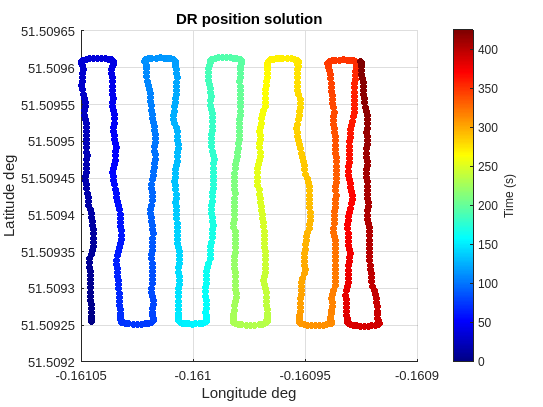

% plot position estimates frrom DR


% position plot with time as cmap
p= scatter(DR_long_deg, DR_lat_deg, 30, epochs, 'filled');  % 'o' specifies the marker style (you can use other markers as well)
colormap(jet);  % Choose colormap (you can change to other colormaps if desired)

% Add colorbar with title
c = colorbar;
xlabel(c, 'Time (s)');  % Label for colorbar

xlabel('Longitude deg');  % Label for x-axis
ylabel('Latitude deg');  % Label for y-axis

title("DR position solution")
grid on;
saveas(gcf,'CW1/Images/DR_pos.png')

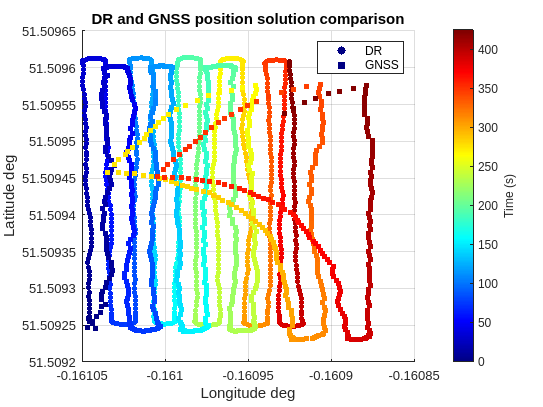

% plot position estimates frrom DR as well as GNSS


% position plot with time as cmap
p= scatter(DR_long_deg, DR_lat_deg, 15, epochs, 'filled');  
p.Marker= "o";
hold on
p2= scatter(GNSS_pos_vel(:, 3), GNSS_pos_vel(:, 2), 15, epochs, 'filled');
p2.Marker= 'square';
colormap(jet);  % Choose colormap (you can change to other colormaps if desired)

% Add colorbar with title
c = colorbar;
xlabel(c, 'Time (s)');  % Label for colorbar

xlabel('Longitude deg');  % Label for x-axis
ylabel('Latitude deg');  % Label for y-axis

legend("DR", "GNSS")
title("DR and GNSS position solution comparison")
grid on;
hold off
saveas(gcf,'CW1/Images/DR_GNSS_pos.png')

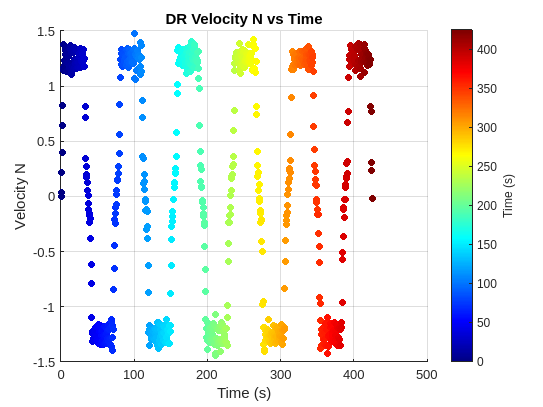

% DR velocity N vs time

% position plot with time as cmap
p= scatter(epochs, DR_speed_N_d, 30, epochs, 'filled');  % 'o' specifies the marker style (you can use other markers as well)
colormap(jet);  % Choose colormap (you can change to other colormaps if desired)

% Add colorbar with title
c = colorbar;
xlabel(c, 'Time (s)');  % Label for colorbar

xlabel('Time (s)');  % Label for x-axis
ylabel('Velocity N');  % Label for y-axis

title("DR Velocity N vs Time")
grid on;
saveas(gcf,'CW1/Images/DR_vel_N.png')

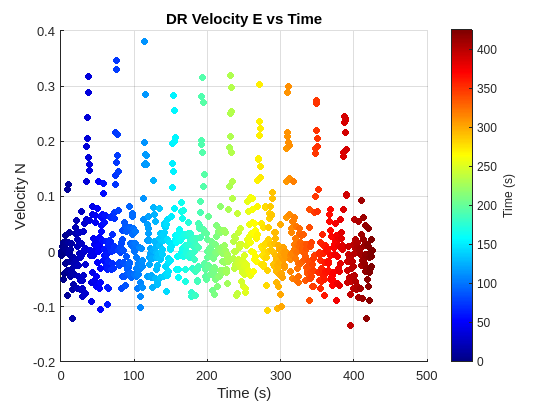

% DR velocity E vs time

% position plot with time as cmap
p= scatter(epochs, DR_speed_E_d, 30, epochs, 'filled');  % 'o' specifies the marker style (you can use other markers as well)
colormap(jet);  % Choose colormap (you can change to other colormaps if desired)

% Add colorbar with title
c = colorbar;
xlabel(c, 'Time (s)');  % Label for colorbar

xlabel('Time (s)');  % Label for x-axis
ylabel('Velocity N');  % Label for y-axis

title("DR Velocity E vs Time")
grid on;
saveas(gcf,'CW1/Images/DR_vel_E.png')

# DR GNSS Integration

GNSS_pos_vel= readmatrix("CW1/CW_GNSS_pos_vel.csv");

epochs= GNSS_pos_vel(:, 1);
GNSS_lat_deg= GNSS_pos_vel(:, 2);
GNSS_lat_rad= GNSS_lat_deg* deg_to_rad;

GNSS_long_deg= GNSS_pos_vel(:, 3); 
GNSS_long_rad= GNSS_long_deg* deg_to_rad;
GNSS_height= GNSS_pos_vel(:, 4);


GNSS_vel_N= GNSS_pos_vel(:, 5);
GNSS_vel_E= GNSS_pos_vel(:, 6);



DR_pos_vel= readmatrix("CW1/CW_DR_pos_vel.csv");

DR_lat_deg= DR_pos_vel(:, 2);
DR_lat_rad= DR_pos_vel(:, 3);

DR_long_deg= DR_pos_vel(:, 4);
DR_long_rad= DR_pos_vel(:, 5);

DR_vel_N_d= DR_pos_vel(:, 6);
DR_vel_E_d= DR_pos_vel(:, 7);

Final columns that will be presented in the report

epochs;

corr_DR_lat= zeros(size(DR_pos_vel, 1), 1); % will be in radians
corr_DR_long= zeros(size(DR_pos_vel, 1), 1);% needs to be changed manually

corr_DR_speed_N_d= zeros(size(DR_pos_vel, 1), 1);
corr_DR_speed_E_d= zeros(size(DR_pos_vel, 1), 1);

heading_data_deg;

We assume for initial uncertainities

sd of 0.05 m/s in velocity measurements 

sd of 10 m for position solution



for index=1: size(epochs, 1)
    if index==1
        est_state_last= zeros(4, 1);
        est_state_err_cov_mat_last= zeros(4, 4);

        v_sd= 0.05;
        est_state_err_cov_mat_last(1, 1)= v_sd^2;
        est_state_err_cov_mat_last(2, 2)= v_sd^2;
        
        
        
        [R_N, R_E]= Radii_of_curvature(GNSS_lat_rad(1));
        h= GNSS_height(1);
        r_sd= 10;
        
        est_state_err_cov_mat_last(3, 3)= r_sd^2 / (R_N+ h )^2;
        est_state_err_cov_mat_last(4, 4)= r_sd^2 / ((R_E+ h )* cos(GNSS_lat_rad(1)))^2;

    else
        est_state_last= est_state_new;
        est_state_err_cov_mat_last= est_state_err_cov_mat_new;

    end


    [corr_DR_speed_N_d(index), corr_DR_speed_E_d(index), corr_DR_lat(index), corr_DR_long(index),...
    est_state_new, est_state_err_cov_mat_new]= Integrate_GNSS_DR_soln(est_state_last, est_state_err_cov_mat_last,...
    GNSS_lat_rad(index), GNSS_long_rad(index), GNSS_height(index), GNSS_vel_N(index), GNSS_vel_E(index),...
    DR_lat_rad(index), DR_long_rad(index), DR_vel_N_d(index), DR_vel_E_d(index),...
    0.5,0.2, 10,  0.05);
    
end

corr_DR_lat = corr_DR_lat* rad_to_deg;
corr_DR_long= corr_DR_long* rad_to_deg;

% Concatenate matrices horizontally
Deliverable1 = horzcat(epochs, ...
    corr_DR_lat, corr_DR_long, ...
    corr_DR_speed_N_d, corr_DR_speed_N_d, ...
    heading_data_deg);
% Save the combined matrix to a CSV file without a header
writematrix(Deliverable1, 'CW1/CW_Deliverable1.csv');
% epoch, lat_rad, lat_rad, v_N,  v_E,  heading


# Plots

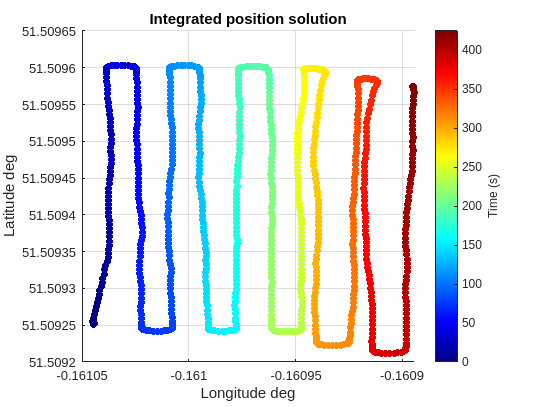

% plot position estimates frrom GNSS+DR


% position plot with time as cmap
p= scatter(corr_DR_long, corr_DR_lat, 30, epochs, 'filled');  % 'o' specifies the marker style (you can use other markers as well)
colormap(jet);  % Choose colormap (you can change to other colormaps if desired)

% Add colorbar with title
c = colorbar;
xlabel(c, 'Time (s)');  % Label for colorbar

xlabel('Longitude deg');  % Label for x-axis
ylabel('Latitude deg');  % Label for y-axis

title("Integrated position solution")
grid on;
saveas(gcf,'CW1/Images/Integrated_pos.png')

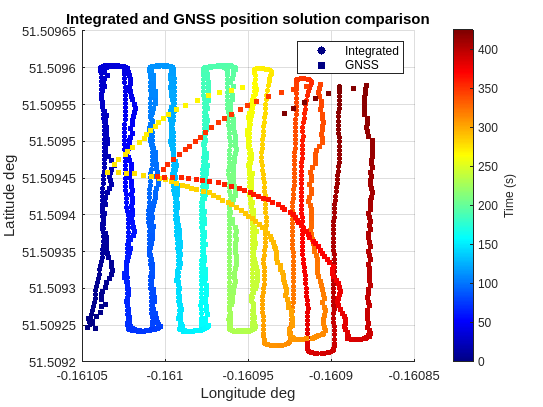

% plot position estimates frrom GNSS+DR as well as GNSS


% position plot with time as cmap
p= scatter(corr_DR_long, corr_DR_lat, 15, epochs, 'filled');  % 'o' specifies the marker style (you can use other markers as well)
p.Marker= "o";
hold on
p2= scatter(GNSS_long_deg, GNSS_lat_deg, 15, epochs, 'filled');
p2.Marker= 'square';
colormap(jet);  % Choose colormap (you can change to other colormaps if desired)

% Add colorbar with title
c = colorbar;
xlabel(c, 'Time (s)');  % Label for colorbar

xlabel('Longitude deg');  % Label for x-axis
ylabel('Latitude deg');  % Label for y-axis

legend("Integrated", "GNSS")
title("Integrated and GNSS position solution comparison")
grid on;
saveas(gcf,'CW1/Images/Integrated_vs_GNSS_pos.png')
hold off

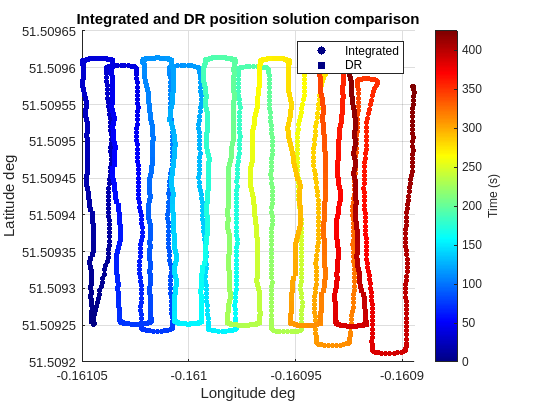

% plot position estimates frrom GNSS+DR as well as DR


% position plot with time as cmap
p= scatter(corr_DR_long, corr_DR_lat, 15, epochs, 'filled');  % 'o' specifies the marker style (you can use other markers as well)
p.Marker= "o";
hold on
p2= scatter(DR_long_deg, DR_lat_deg, 15, epochs, 'filled');
p2.Marker= 'square';
colormap(jet);  % Choose colormap (you can change to other colormaps if desired)

% Add colorbar with title
c = colorbar;
xlabel(c, 'Time (s)');  % Label for colorbar

xlabel('Longitude deg');  % Label for x-axis
ylabel('Latitude deg');  % Label for y-axis

legend("Integrated", "DR")
title("Integrated and DR position solution comparison")
grid on;
saveas(gcf,'CW1/Images/Integrated_vs_DR_pos.png')
hold off